# Diskret Stokastisk

## Eksempel 1

 Uniformt fordelt - Middelværdi = 0, varians = 10

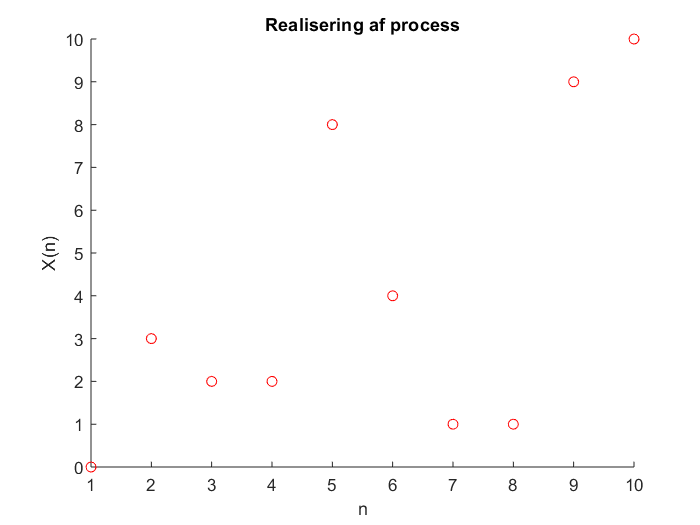

clearvars
close all
% Antal samples
count = 10;
max = 10;
% unidrnd laver tal mellem 1 og max, inklusive. Vi skal bruge tal fra 0 til 10
% Derfor genererer vi tal mellem 1 og 11. Dernæst trækkes 1 fra igen.
Xn = unidrnd(max+1,1,count)-1; % Max værdi = 10, output i et 1*count array
x = 1:1:10;
figure(1)
hold on
title("Realisering af process"); xlabel("n"); ylabel("X(n)");
scatter(x,Xn,'or')

## Eksempel 2

 Gausisk fordelt, middelværdi 0, varians 1

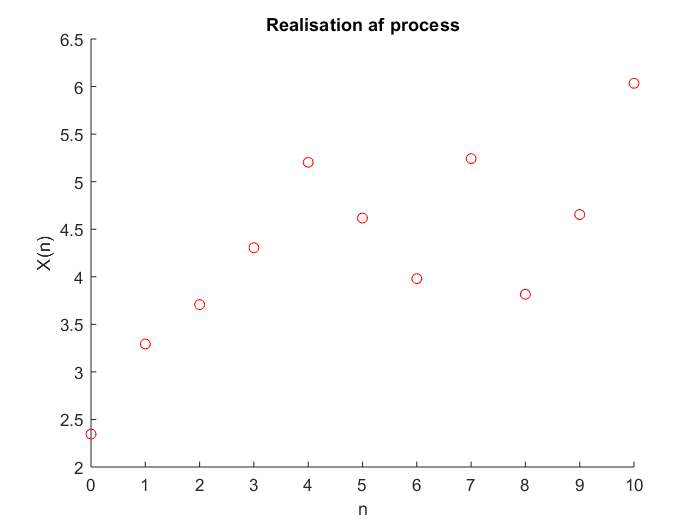

clearvars
close all
%antal samples
samples = 10;
mean = 0; variance = 1; sigma = sqrt(variance);
% Først træk normalfordelte værdier til w(n)
w = normrnd(mean, sigma, [1 samples+1]);
Xn = w+4;
figure(1)
x = [0:samples];
hold on
title("Realisation af process"); xlabel("n"); ylabel("X(n)");
scatter(x, Xn,'or')

## Eksempel 3

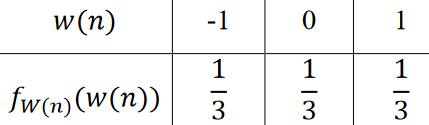

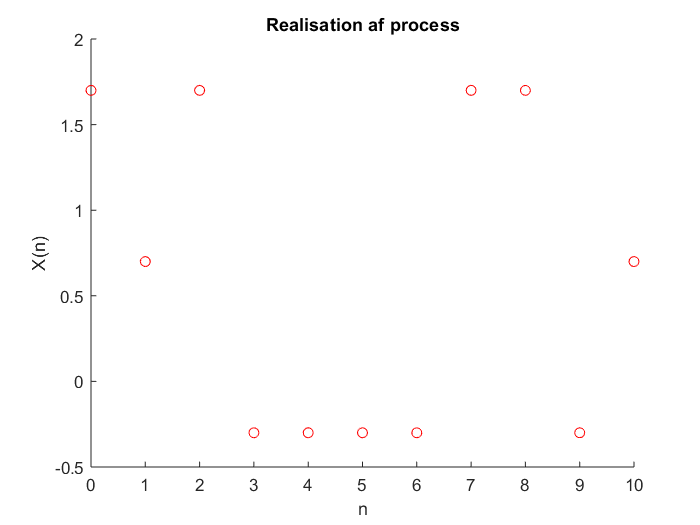

clearvars
close all
x = 0:1:10;
samples = length(x);
% Unidrnd genererer tal fra 1 til max, og vi skal derfor shifte vores talrække, og dernæst trække fra
% -1 til 1 skal rykkes så laveste tal er 1, det vil sige vi lægger 2 til alle tal. 
% Max er derfor 3
% Dernæst trækkes 2 fra igen, og der lægges 0.7 til ift. funktionen for X(n)
w = unidrnd(3, 1, samples) - 2 + 0.7;
figure(1);
hold on
xlabel("n"); ylabel("X(n)"); title("Realisation af process");
scatter(x, w, 'or')

## Eksempel 4

    

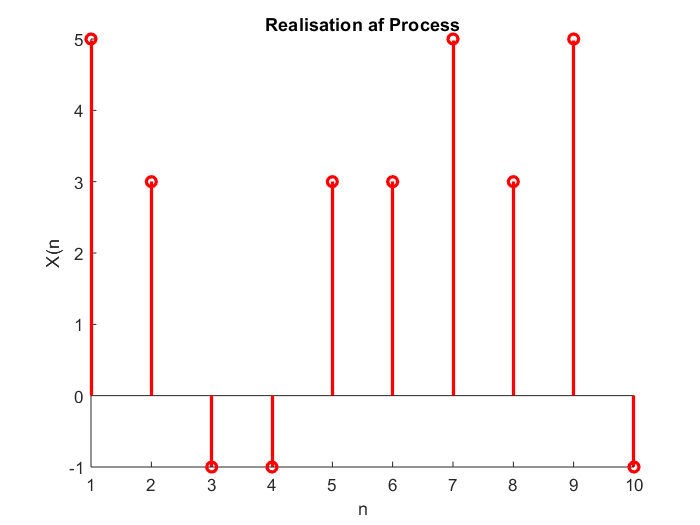

clearvars
close all
x = 1:1:10;
samples = length(x);
% Da unidrnd genereer fra 1 til max skal vi lige rykke tallene 1, og så trække fra igen
w = unidrnd(4, 1, samples) - 1;
Xn = (2*w)-1;
figure(1);
hold on
xlabel("n"); ylabel("X(n"); title("Realisation af Process");
stem(x,Xn,'-r','LineWidth',2)

# Kontinuer Stokastisk

## Eksempel 1

clearvars
close all
% Antal realisationer
N = 5;
t_start = 0;
t_end = 7;
interval = t_end-t_start;
mean = 5; variance = 1; sigma = sqrt(variance);
w = normrnd(mean, sigma, [1 N+1])

w =     5.9801    3.2742    6.2040    3.9702    3.0552    5.0748


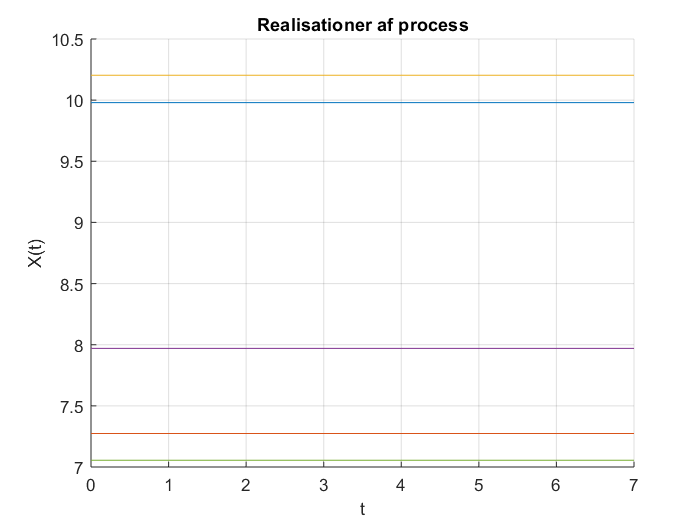

t = t_start:1:t_end;
figure(1)
hold on
grid
xlabel("t"); ylabel("X(t)"); title("Realisationer af process");
for i=1:N
    y = w(i)+4;
    plot(t, ones(1,length(t))*y);    
end

## Eksempel 2

                    

clearvars
close all
t = 0:0.1:0.9;
mean = t; variance = 1; sigma = sqrt(variance);
w = normrnd(mean, sigma, [1 length(t)])

w =     1.1309    1.3239   -0.1931    0.9896    0.2760    0.3080    1.7505    0.9387    1.7617    1.3898


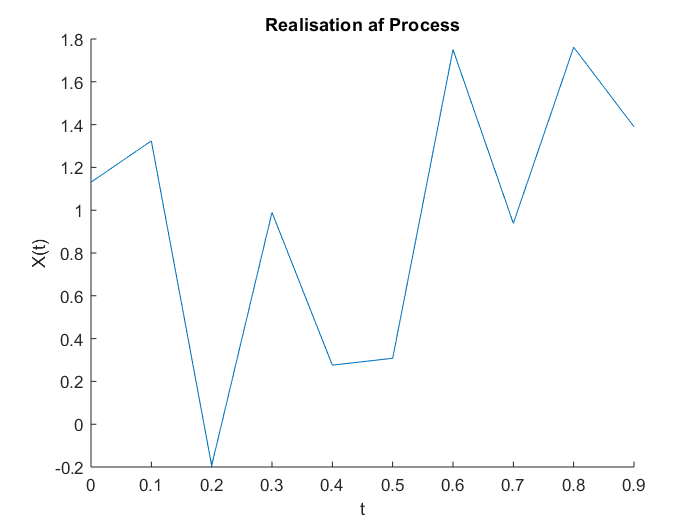

figure(1)
hold on;
xlabel("t"); ylabel("X(t)"); title("Realisation af Process");
plot(t, w)

## Eksempel 3

            

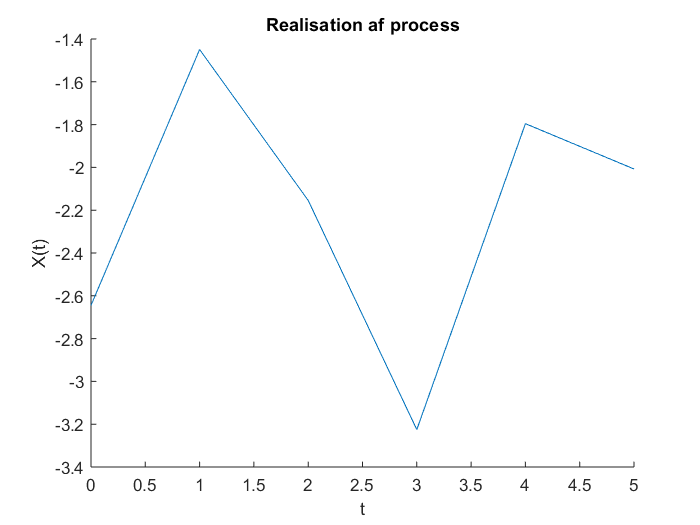

clearvars
close all
x = 0:1:5;
samples = length(x);
w = randn(1,samples)-2;
figure(1)
hold on
xlabel("t"); ylabel("X(t)"); title("Realisation af process");
plot(x, w)

## Eksempel 4

     

N kan uafhængigt antage værdierne 0 eller 1 med lige stor sandsynlighed

clearvars
close all
x = 0:1:5;
realisationer = 3;
% Først få værdierne til n
n = randi([0, 1], 1, 3)

n =      1     1     0


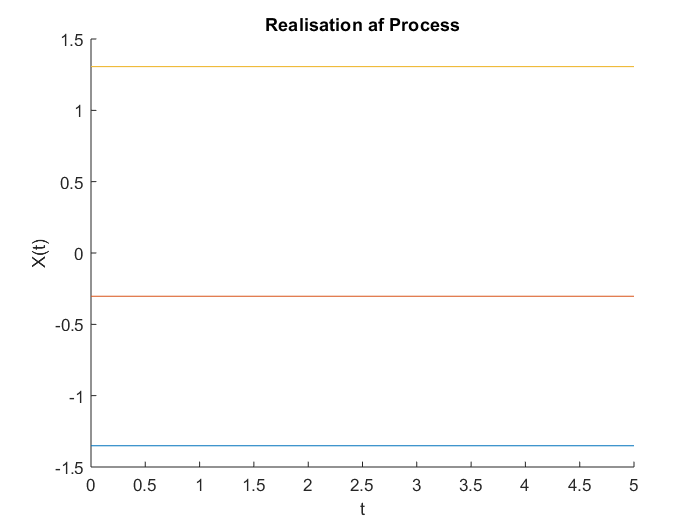

% Ud fra W~N(0; 0,25) kan vi udlede:
mean = 0; variance = 0.25; sigma = sqrt(variance);

% Få værdierne til w
w = randn(1, 3) * sigma;
figure(1)
hold on
xlabel("t"); ylabel("X(t)"); title("Realisation af Process");
for i = 1:realisationer
    y = (-1)^n(i) + w(i);
    plot(x, ones(1,length(x))*y);
end

## Eksempel 5

     

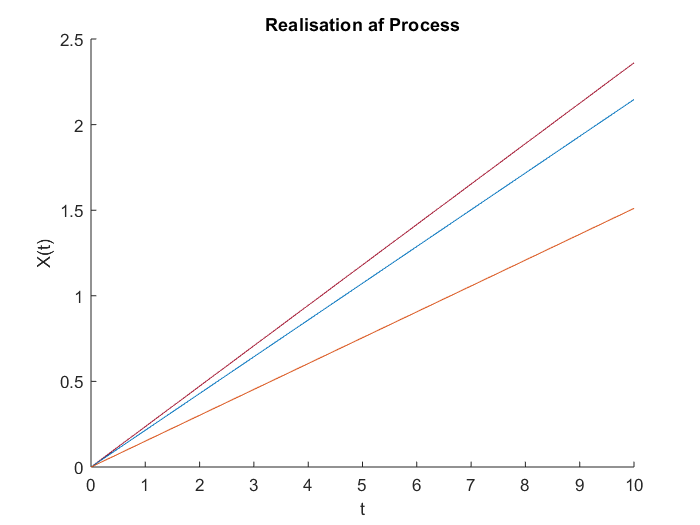

clearvars
close all
syms t
realisationer = 3;
mean = 1; variance=0.25;sigma=sqrt(variance);
a = randn(1,realisationer) * sigma;
figure(1)
hold on
xlabel("t"); ylabel("X(t)"); title("Realisation af Process");
for i = 1:realisationer
    y = a*t;
    fplot(y,[0 10])
end